num = input("Which test number would you like to load (e.g. 1)? ","s");
num = str2num(num);
loadedData = load(sprintf("test%i.mat", num));
retrievedData = loadedData.fullData.data(2,:);
loadedData.fullData.metadata.description

ans =     "Amplitude: 0.50 - 3.00 
     Attenuation: 0.10 - 2.00 
     Spacing: 5.00 - 6.00 
     Frequency: 3.00 - 10.00 
     "


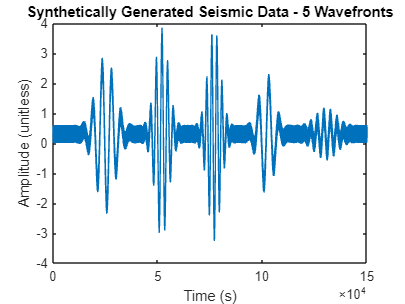

save('loaded_test_data.mat', 'retrievedData');
plot(retrievedData)
title("Synthetically Generated Seismic Data - 5 Wavefronts")
xlabel("Time (s)")
ylabel("Amplitude (unitless)")